% Load the training data 
data = load("trainingData_PreCropped.mat");
trainingData = data.trainingData;


% % Specify the directory in which training samples are stored. 
% % Add full path to the file names in training data.
% dataDir = "D:\college\FYP\Scripts\Object_Detection\ACF\version\v2\ACF_Training_Data";
% 
% % Update imageFilename values with full paths.
% for i = 1:height(trainingData)
%     trainingData.imageFilename{i} = fullfile(dataDir, trainingData.imageFilename{i});
% end


% % Randomly shuffle data for training.
% rng(0);
% shuffledIdx = randperm(height(trainingData));
% trainingData = trainingData(shuffledIdx,:);


% Create an imageDatastore using the files from the table.
imds = imageDatastore(trainingData.imageFilename);

% Create a boxLabelDatastore using the label columns from the table.
blds = boxLabelDatastore(trainingData(:,2:end));

% Combine the datastores.
ds = combine(imds, blds);

% Load a preinitialized YOLO v2 object detection network.
net = load('yolov2VehicleDetector.mat');
lgraph = net.lgraph

lgraph =   LayerGraph with properties:

     InputNames: {'input'}
    OutputNames: {'yolov2OutputLayer'}
         Layers: [25×1 nnet.cnn.layer.Layer]
    Connections: [24×2 table]


lgraph.Layers

ans =   25×1 Layer array with layers:

     1   'input'               Image Input                128×128×3 images
     2   'conv_1'              2-D Convolution            16 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'BN1'                 Batch Normalization        Batch normalization
     4   'relu_1'              ReLU                       ReLU
     5   'maxpool1'            2-D Max Pooling            2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv_2'              2-D Convolution            32 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     7   'BN2'                 Batch Normalization        Batch normalization
     8   'relu_2'              ReLU                       ReLU
     9   'maxpool2'            2-D Max Pooling            2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'conv_3'              2-D Convolution 


% Configure the network training options.
options = trainingOptions('sgdm',...
          'InitialLearnRate',0.001,...
          'Verbose',true,...
          'MiniBatchSize',16,...
          'MaxEpochs',30,...
          'Shuffle','never',...
          'VerboseFrequency',30,...
          'CheckpointPath',tempdir);

% Train the YOLO v2 network.
[detector,info] = trainYOLOv2ObjectDetector(ds,lgraph,options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* TrafficSign

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         8.36 |         69.9 |          0.0010 |
|      30 |          30 |       00:00:45 |         0.53 |          0.3 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.
Detector training complete.
*************************************************************************



detector

detector =   yolov2ObjectDetector with properties:

            ModelName: 'TrafficSign'
              Network: [1×1 DAGNetwork]
    TrainingImageSize: [128 128]
          AnchorBoxes: [4×2 double]
           ClassNames: TrafficSign


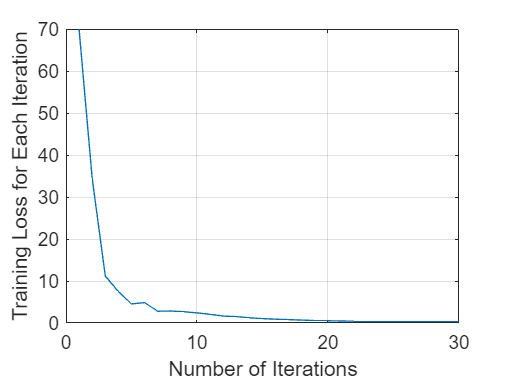

% You can verify the training accuracy by inspecting the training loss for each iteration.

figure
plot(info.TrainingLoss)
grid on
xlabel('Number of Iterations')
ylabel('Training Loss for Each Iteration')

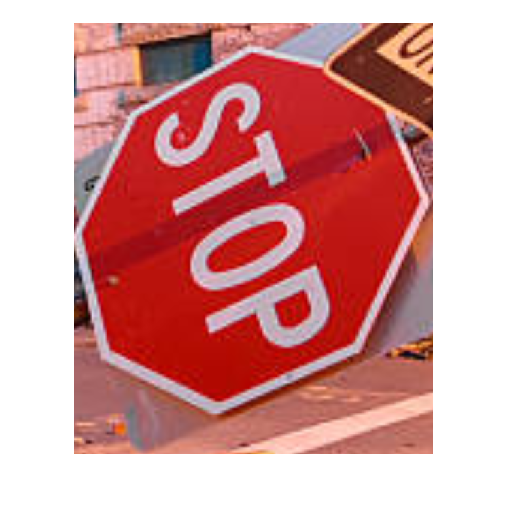

img = imread("C:\Users\Calm\Downloads\s1.png");

[bboxes,scores] = detect(detector,img);

if(~isempty(bboxes))
    img = insertObjectAnnotation(img,'rectangle',bboxes,scores);
end
figure
imshow(img)